s = 5;
a = 1;
b = 0;
c = 1;
e = s*(s-1)/2;    %number of states
lambda = 2453.7/e;%encounter rate of all nodes 
encounterN = ceil(7000/lambda);  %number of encounter
thr = 0.3;

[transSto, N, VStep, MStep, req_n, cont_n] = genTransMatrixSto(s, a, b, c, lambda);


% Lambda = 300;    
% init_state = zeros(1,size(transSto,1)); init_state(1) = 1;
% [estm_state_n, p]=initDist_v2(thr, Lambda, lambda, init_state, transSto, e, s);
% [t, binVal ] = delayPDFsto( transSto, estm_state_n, encounterN, cont_n, lambda);
% hold on;
% plot(t,binVal/(s-1),'DisplayName', ['prefprobability' num2str(estm_state_n(1))]);
% p

% Lambda = 300;
% init_state = zeros(1,size(transSto,1)); init_state(1) = 1;
% [estm_state_n, p]=initDist_v2(thr, Lambda, lambda, init_state, transSto, e, s);
% [t, binVal ] = delayPDFsto( transSto, estm_state_n, encounterN, cont_n, lambda);
% hold on;
% plot(t,binVal/(s-1),'DisplayName', 'lower bound');
% % plot(t,binVal/(s-1),'DisplayName', ['prefprobability' num2str(estm_state_n(1))]);
% p

ini = zeros(1,size(transSto,1));ini(1) = 1;
[t, conBinVal ] = delayPDFsto( transSto, ini, encounterN, cont_n, lambda);
plot(t,conBinVal/(s-1),'DisplayName', 'CON');


Lambda = 900;
init_state = zeros(1,size(transSto,1)); init_state(1) = 1;
[estm_state_n, p]=initDist_v2(thr, Lambda, lambda, init_state, transSto, e, s);
[t, binVal ] = delayPDFsto( transSto, estm_state_n, encounterN, cont_n, lambda);
% p=0.1;
% binVal = binVal*(1-p) + conBinVal*p;
p

p = 0.3955

hold on;
plot(t,binVal/(s-1),'DisplayName', 'FAP');
p

p = 0.3955

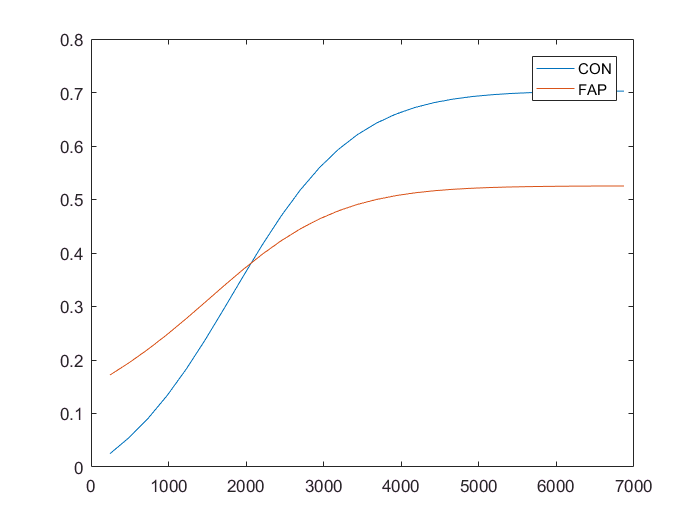


legend('show');

% plot(t,binVal/(s-1),'DisplayName', ['prefprobability' num2str(ini(1))]);

% ini = zeros(1,size(transSto,1));ini(1) = 0;ini(3) = 1 - ini(1);
% [t, binVal ] = delayPDFsto( transSto, ini, encounterN, cont_n, lambda);
% plot(t,binVal/(s-1),'DisplayName', ['prefprobability' num2str(ini(1))]);



esto=[];
csto=[];
psto=[];
pref_f = [];

a=esto;
content_num_process;

Not enough input arguments.

Error in content_num_process (line 16)
        pref_f = 0:max(raw(:,3));

econ = con_m/(s-1);

plot( ( (0:size(econ,1)-1)*20 ) ,econ, 'DisplayName', 'cs4k');



a=csto;
content_num_process;
ccon = con_m/(s-1);

%con_m = con_n(:,1)/max(a(:,3))/(s-1);
hold on;
plot( ( (0:size(ccon,1)-1)*20 ) ,ccon, 'DisplayName', 'cs2k');
legend('show');
hold off;
% cost = econ - ccon;

% for i = 2:17
% ut(i)=gain(1)*(1-cost((i*100-180)/20) ) ;
% end


a=psto;
pref_f = unique(pref_f);
content_num_processOCP;
econ = con_m/(s-1);
hold on;    
plot( ( (0:size(econ,1)-1)*20 ) ,econ, 'DisplayName', 'OCP');
legend('off');
legend('show');
hold off;

edelay =[];
cdelay =[];

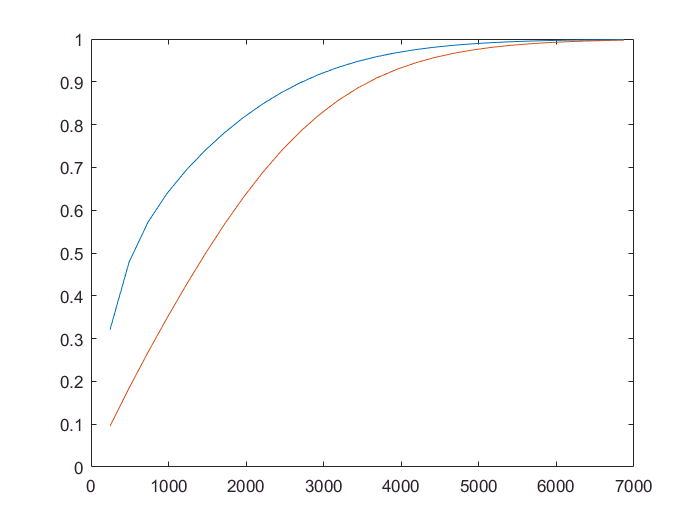

a = 1;
[trans,~] = genTransMatrix(s, a, b, c, lambda);
estm_state_delay = [estm_state_n(1,1:e) sum(estm_state_n(1,(e+1):(e+s-1)))];
[ggpdf, ~ ] = delayCDF_v3( trans,estm_state_delay, encounterN, e, lambda ); 
figure; 
plot((1:(encounterN-1))*lambda,ggpdf, 'DisplayName', 'FAP'); 

% hold on;
% cdfBinVal = cumsum(binVal);
% plot(lambda*(0:25),[0 cdfBinVal(1:25)], 'DisplayName', 'FAP'); 
hold on;
ini = zeros(1,e+1);ini(1) = 1; 
[conggpdf, ~ ] = delayCDF_v3( trans,ini(1:(e+1)), encounterN, e, lambda ); 
plot((1:(encounterN-1))*lambda,conggpdf, 'DisplayName', 'CON'); 

ccdf = histogram(cdelay,'BinWidth',200,'Normalization','cdf');



pref_f = unique(pref_f);
pref_delay = edelay(:,1)==pref_f(1);
for i=2:size(pref_f)
    pref_delay = pref_delay | edelay(:,1)==pref_f(i);
end
pref_delay=edelay(pref_delay,2);
hold on;
ecdf = histogram(pref_delay,'BinWidth',200,'Normalization','cdf');


[ggpdf, ~ ] = delayPDF_v3( trans,estm_state_delay, 200, e, lambda ); 
figure; 
plot(0:60:6000,ggpdf, 'DisplayName', 'FAP'); 
ini = zeros(1,e+1);ini(1) = 1; 
[ggpdf, binVal ] = delayPDF_v3( trans,ini(1:(e+1)), 200, e, lambda ); 
hold on;
plot(0:60:6000,ggpdf, 'DisplayName', 'CON'); 
hold on;
ecdf = histogram(pref_delay,'BinWidth',200,'Normalization','pdf');


[ggpdf, binVal ] = delayCDF_v3( trans,estm_state_delay, 200, e, lambda ); 
cdfBinVal = cumsum(binVal);
figure; 
plot(lambda*(1:25),cdfBinVal(1:2), 'DisplayName', 'FAP'); 
hold on; 
plot(0:60:6000,ggpdf, 'DisplayName', 'FAP'); 


gain = ggpdf-conggpdf;
cost = (binVal - conBinVal)/(s-1);
utility = gain.*(1-cost);
figure;
plot((1:(encounterN-1))*lambda, utility); 